# Stochastic Dynamic Models

We will use the CompEcon Toolbox solvers:

- ddpsolve()    -   Solves discrete-state/action dynamic program

## Example 1: Water Management Model

### Problem Statement:

Water from a reservoir can be used for either irrigation or recreation. Irrigation during the spring benefits farmers but reduces the reservoir level during the summer, damaging the interests of recreational users. Specifically, if the reservoir contains $s$units of water at the beginning of the year and $x$ units are released for irrigation, farmer and recreational user benefits during the year will be $F(x)$ and $U(s-x)$, respectively. Reservoir levels are replenished by random rainfall during the winter. Specifically, it rains $k$ units with probability $p(r)$, for $r=0,1,2,...,R$. The reservoir can hold $M$ units of water, and excess rainfall flows out without benefit to either farmer or recreational user.

What irrigation policy maximizes the sum of farmer and recreational user benefits over an infinite time horizon?

% DEMDDP05 Water Management Model
% This program solves the water management model under the high rainfall
% scenario.
  fprintf('\nDEMDDP05 WATER MANAGEMENT MODEL\n')


DEMDDP05 WATER MANAGEMENT MODEL


  clc;clear;
  close all
  figure('units','normalized','outerposition',[0 0 0.75 1]) % make plot window open to X-fraction of screen
  figure(1);

% Enter model parameters
  alpha1 = 14;                      % producer benefit function parameter
  beta1  = 0.8;                     % producer benefit function parameter
  alpha2 = 10;                      % recreational user benefit function parameter
  beta2  = 0.4;                     % recreational user benefit function parameter  
  maxcap = 30;                      % maximum dam capacity
  r      = [0 1 2 3 4];             % rain levels
  p      = [0.2 0.5 0.1 0.1 0.1,
            0.1 0.1 0.5 0.2 0.1];   % rain probabilities
  delta  = 0.9;                     % discount factor

% Construct state space
  S = (0:maxcap)';              % vector of states
  n = length(S);                % number of states

% Construct action space
  X = (0:maxcap)';              % vector of actions
  m = length(X);                % number of actions

% Construct reward function

  f = zeros(n,m);
  
  for i=1:n
    for k=1:m
        
        if k>i
            
            f(i,k) = -inf;
        
        else
            
            f(i,k) = alpha1 * X(k).^beta1 + alpha2 * (S(i) - X(k)).^beta2; 
        
        end
  
    end
 
  end

% Construct state transition matrix

  P = zeros(size(p,1),m,n,n);  
  for l = 1:size(p,1)
  for k=1:m
    for i=1:n
        for j=1:size(p,2)
      
            snext = min( S(i) - X(k) + r(j), maxcap );
        
            inext = getindex(snext, S);
        
            P(l,k,i,inext) = P(l,k,i,inext) + p(l,j);
        end
    end
  end
  end

% Pack model structure
for l = 1: size(p,1)
  clear model
  model.reward     = f;
  model.transprob  = reshape(P(l,:,:,:),[m,n,m]);
  model.discount   = delta;
  
  % Solve infinite-horizon model using policy iteration

  [v,x,pstar] = ddpsolve(model);
  xc(:,l) = x;
  vc(:,l) = v;
  pstarc(:,:,l) = pstar;
end

Solve Bellman equation via Newton method
    1    1.7e+03
    2    7.0e+02
    3    1.6e+02
    4    1.7e+01
    5    9.3e-01
    6    1.2e-02
    7    0.0e+00
Solve Bellman equation via Newton method
    1    2.3e+03
    2    5.3e+02
    3    1.3e+02
    4    1.8e+01
    5    9.1e-01
    6    2.0e-01
    7    0.0e+00


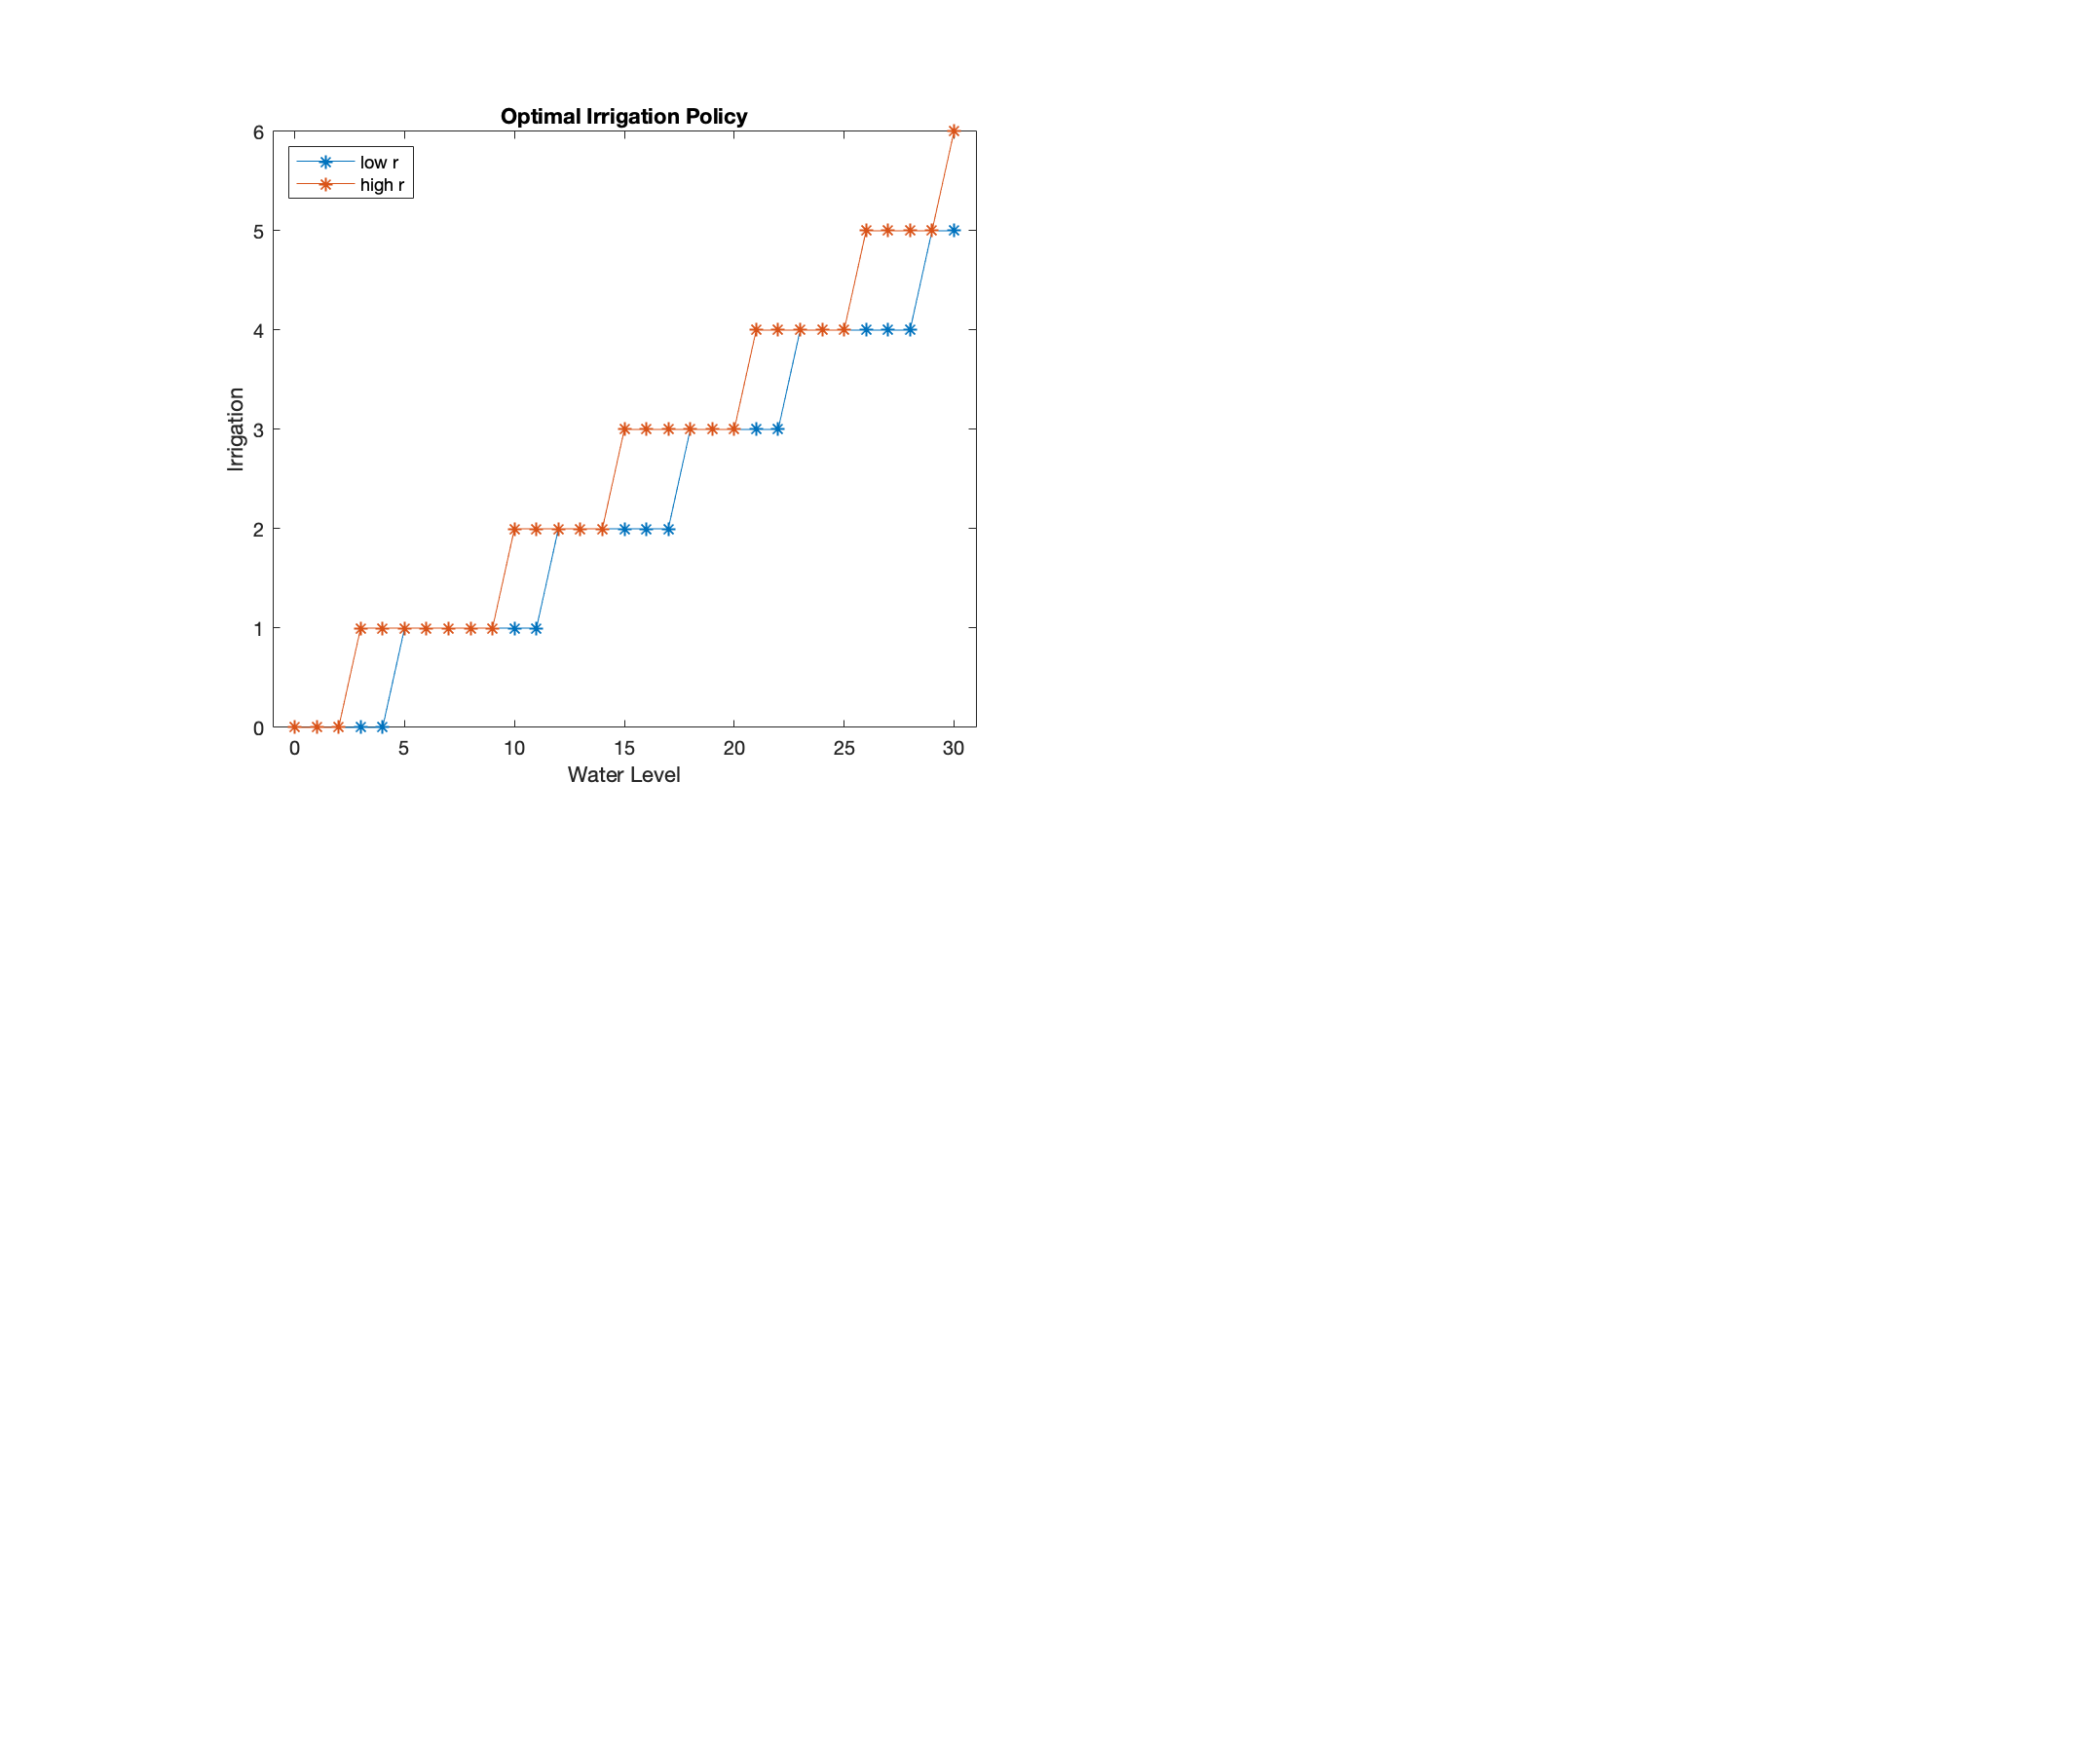

% Plot optimal policy
  subplot(2,2,1); 
  h=plot(S, X(xc), '-*'); 
  title('Optimal Irrigation Policy');
  xlabel('Water Level'); ylabel('Irrigation');
  xlim([-1 31])
  ylim([0 6])
  legend({'low r', 'high r'},'Location','northwest');

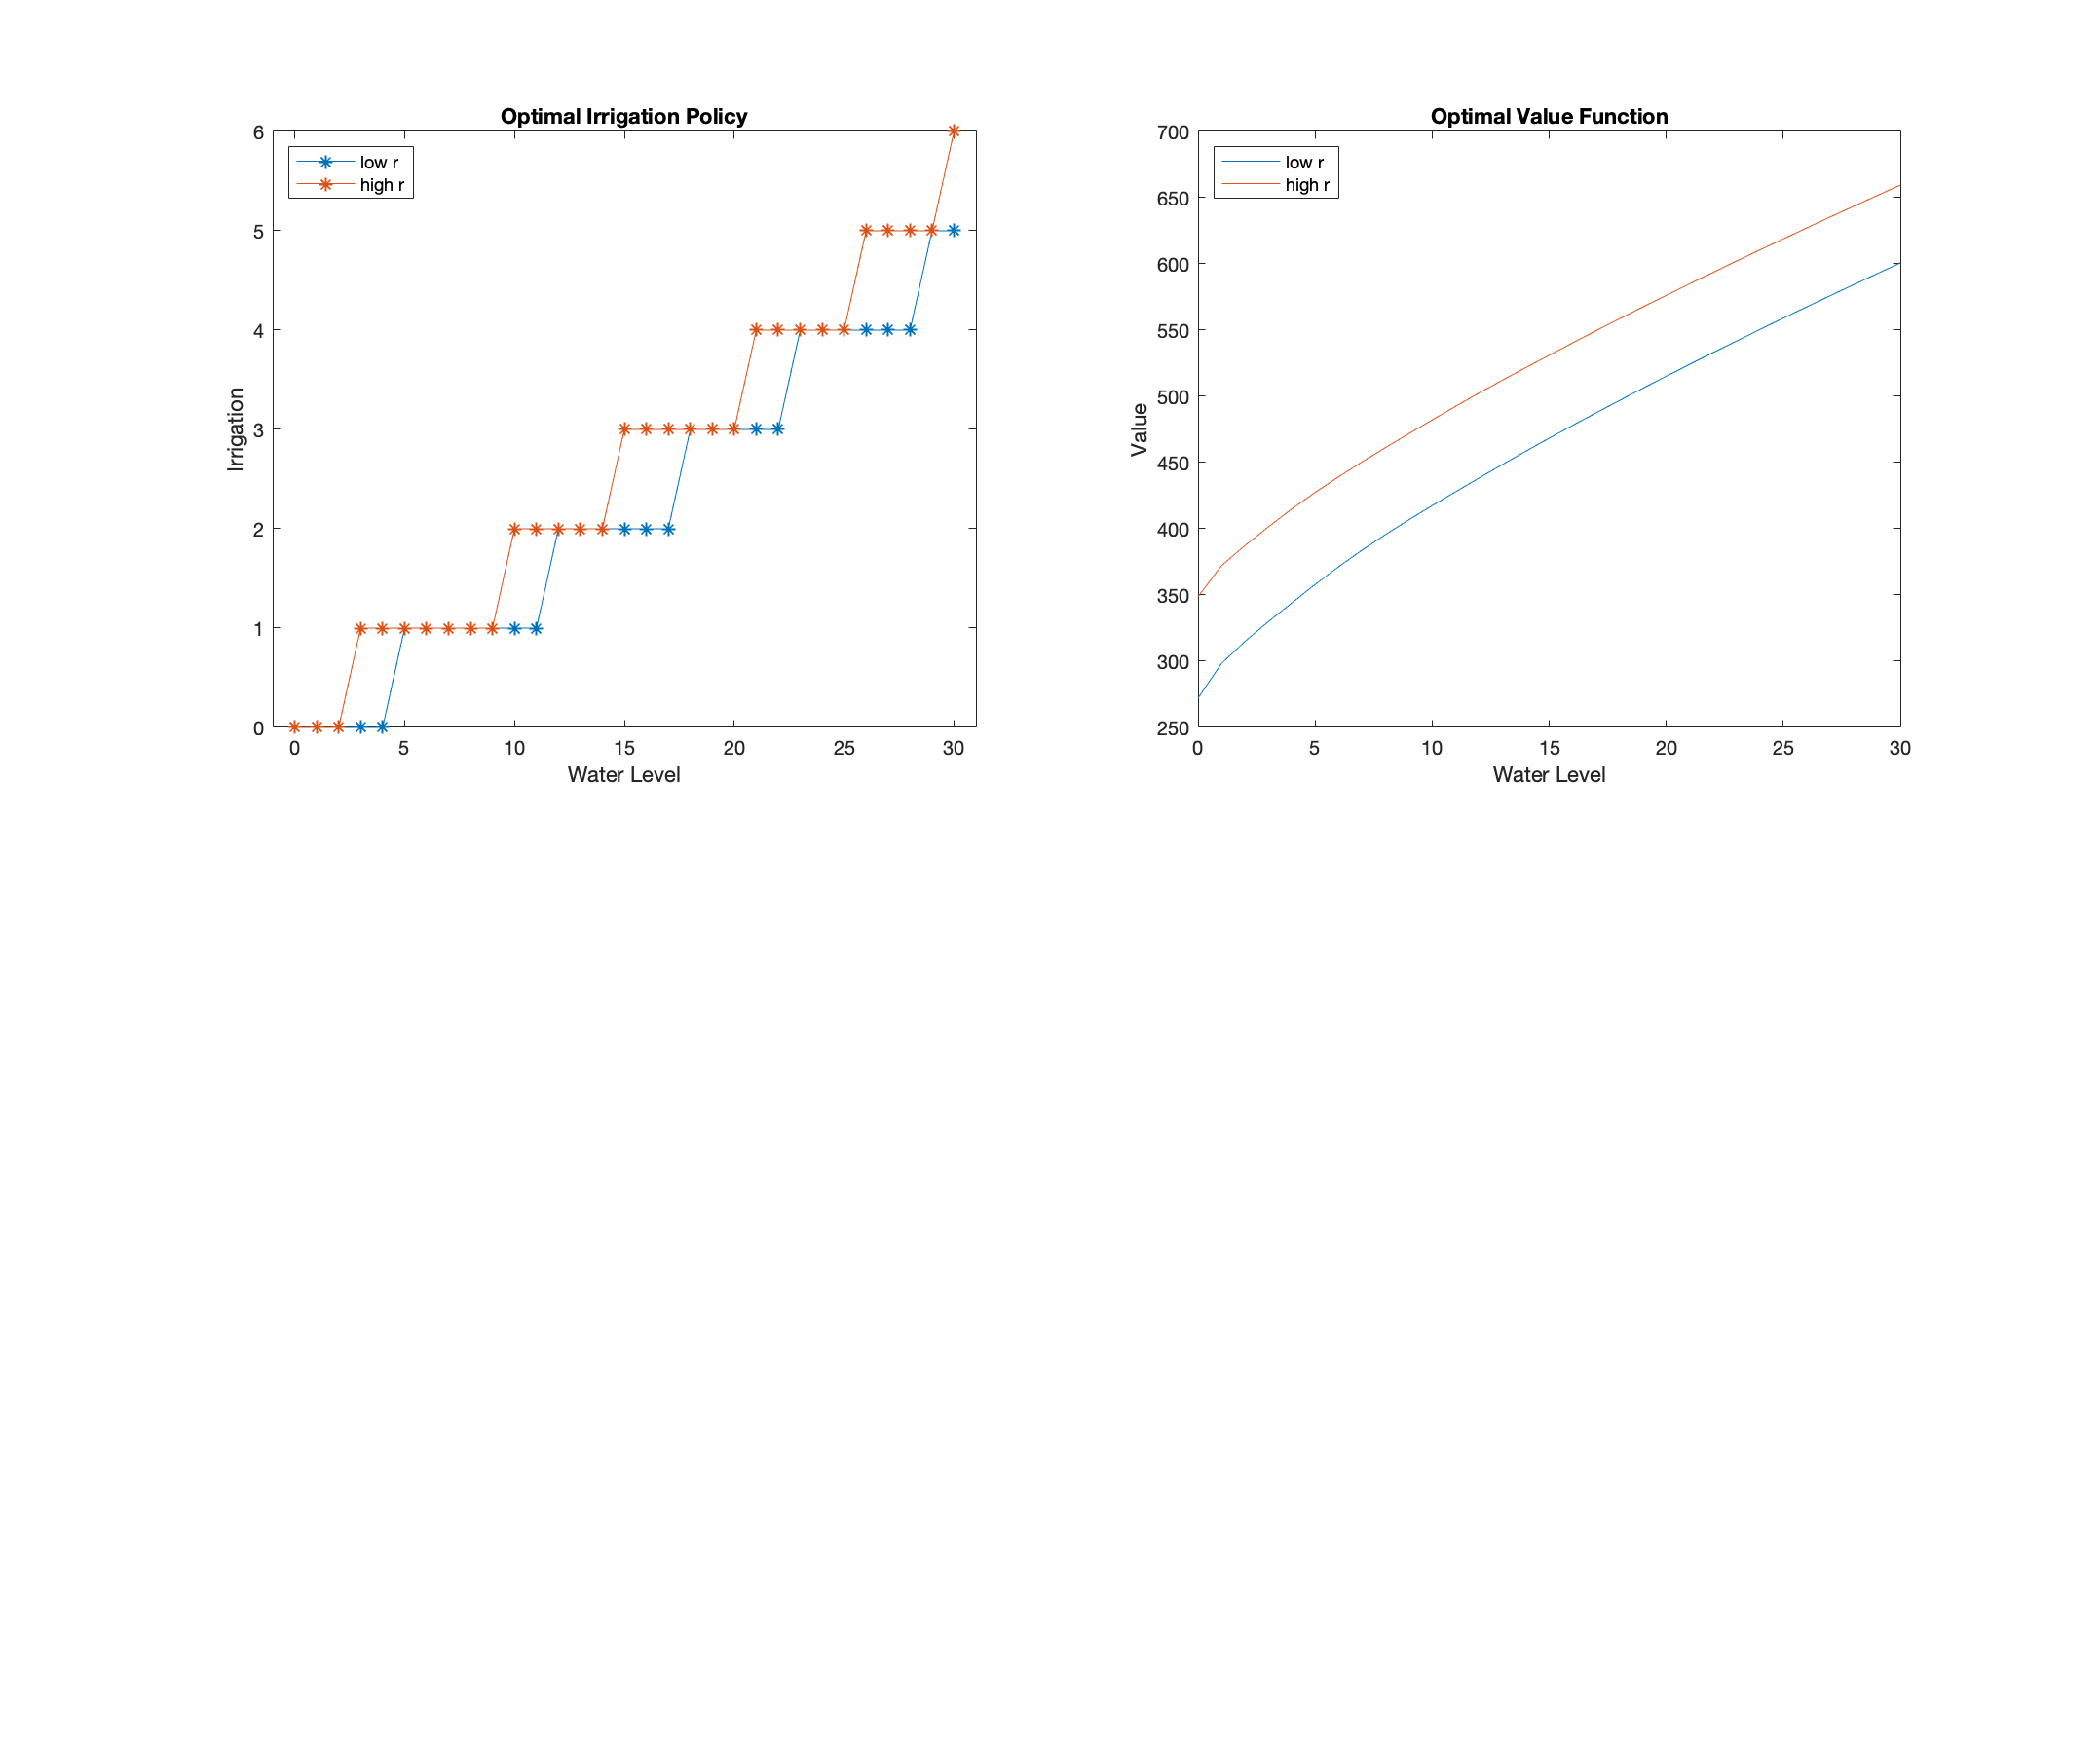

% Plot optimal value function
  subplot(2,2,2); 
  plot(S, vc); 
  title('Optimal Value Function');
  xlabel('Water Level'); ylabel('Value');
  legend({'low r', 'high r'},'Location','northwest');

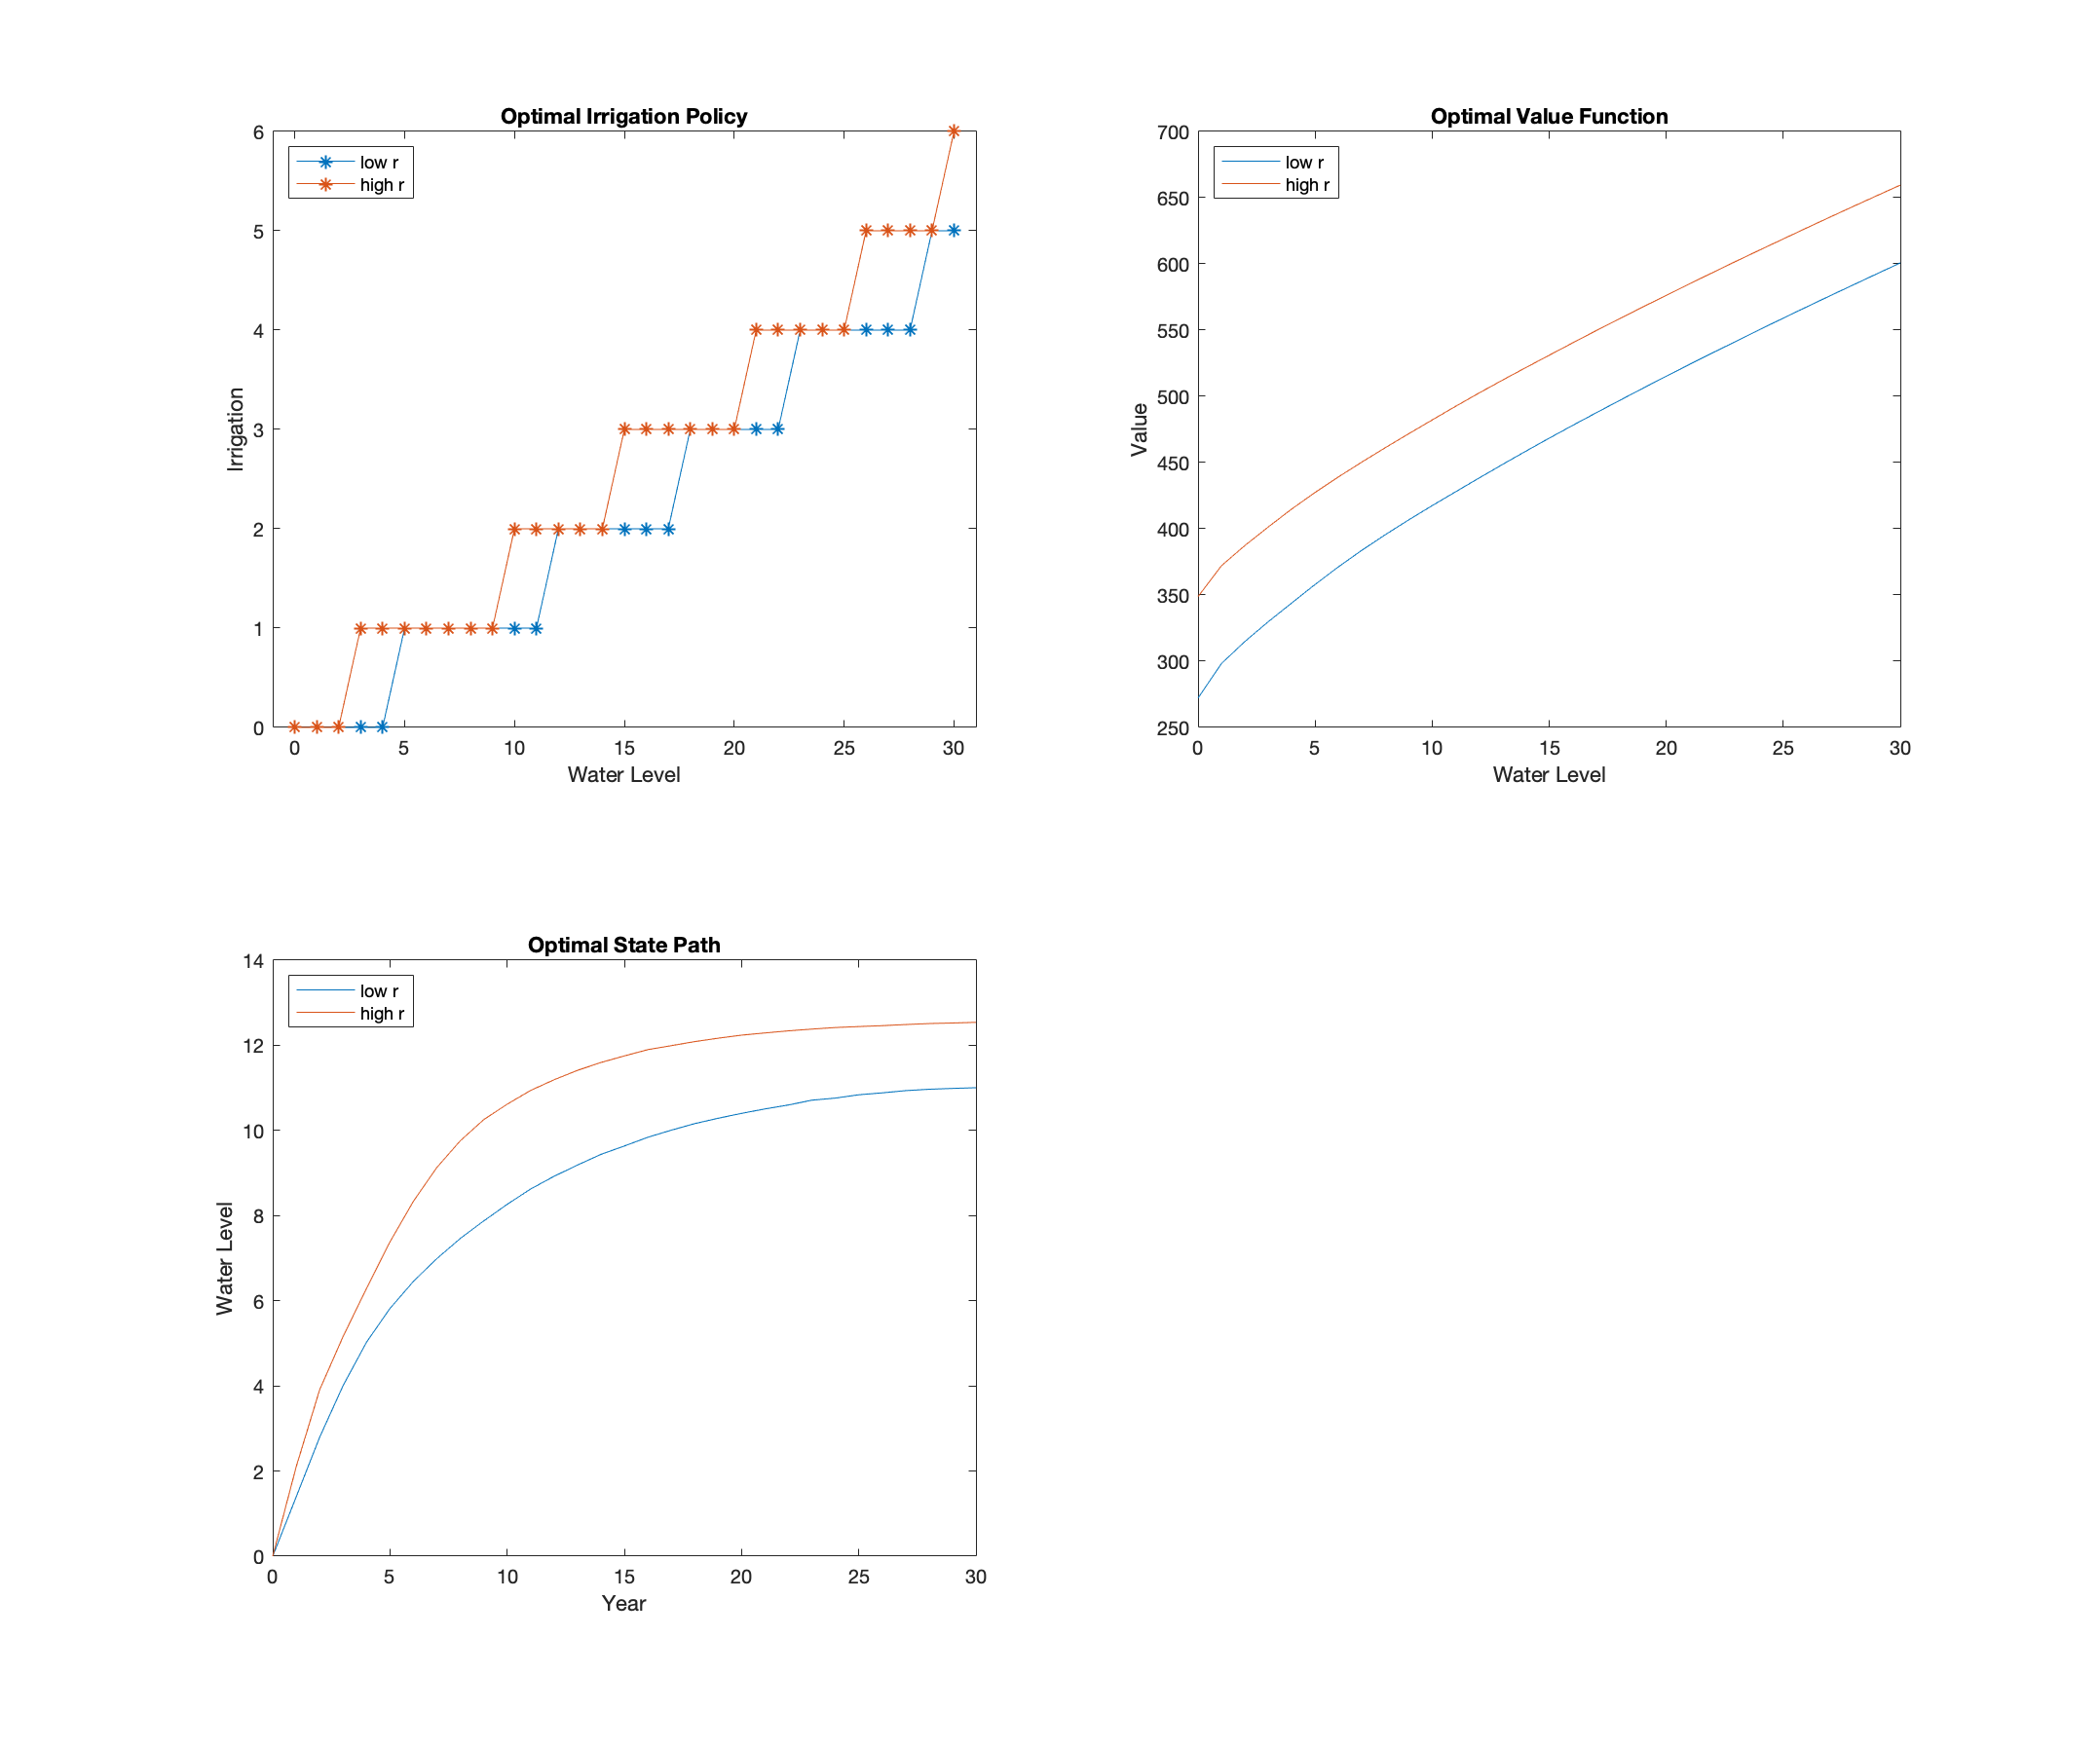

% Generate random optimal paths, starting from zero water level
  for l = 1:2
      sinit = ones(10000, 1); 
      nyrs  = 30;
      pstar = pstarc(:,:,l);
      spath = ddpsimul(pstar, sinit, nyrs);
      mspath = mean(S(spath));
      spathc(l,:) = mspath;
  end
  % Plot expected water level over time, starting from zero water level
  subplot(2,2,3); 
  plot(0:nyrs, spathc);
  title('Optimal State Path'); 
  xlabel('Year'); ylabel('Water Level');
  ylim([0 14])
  legend({'low r', 'high r'},'Location','northwest');

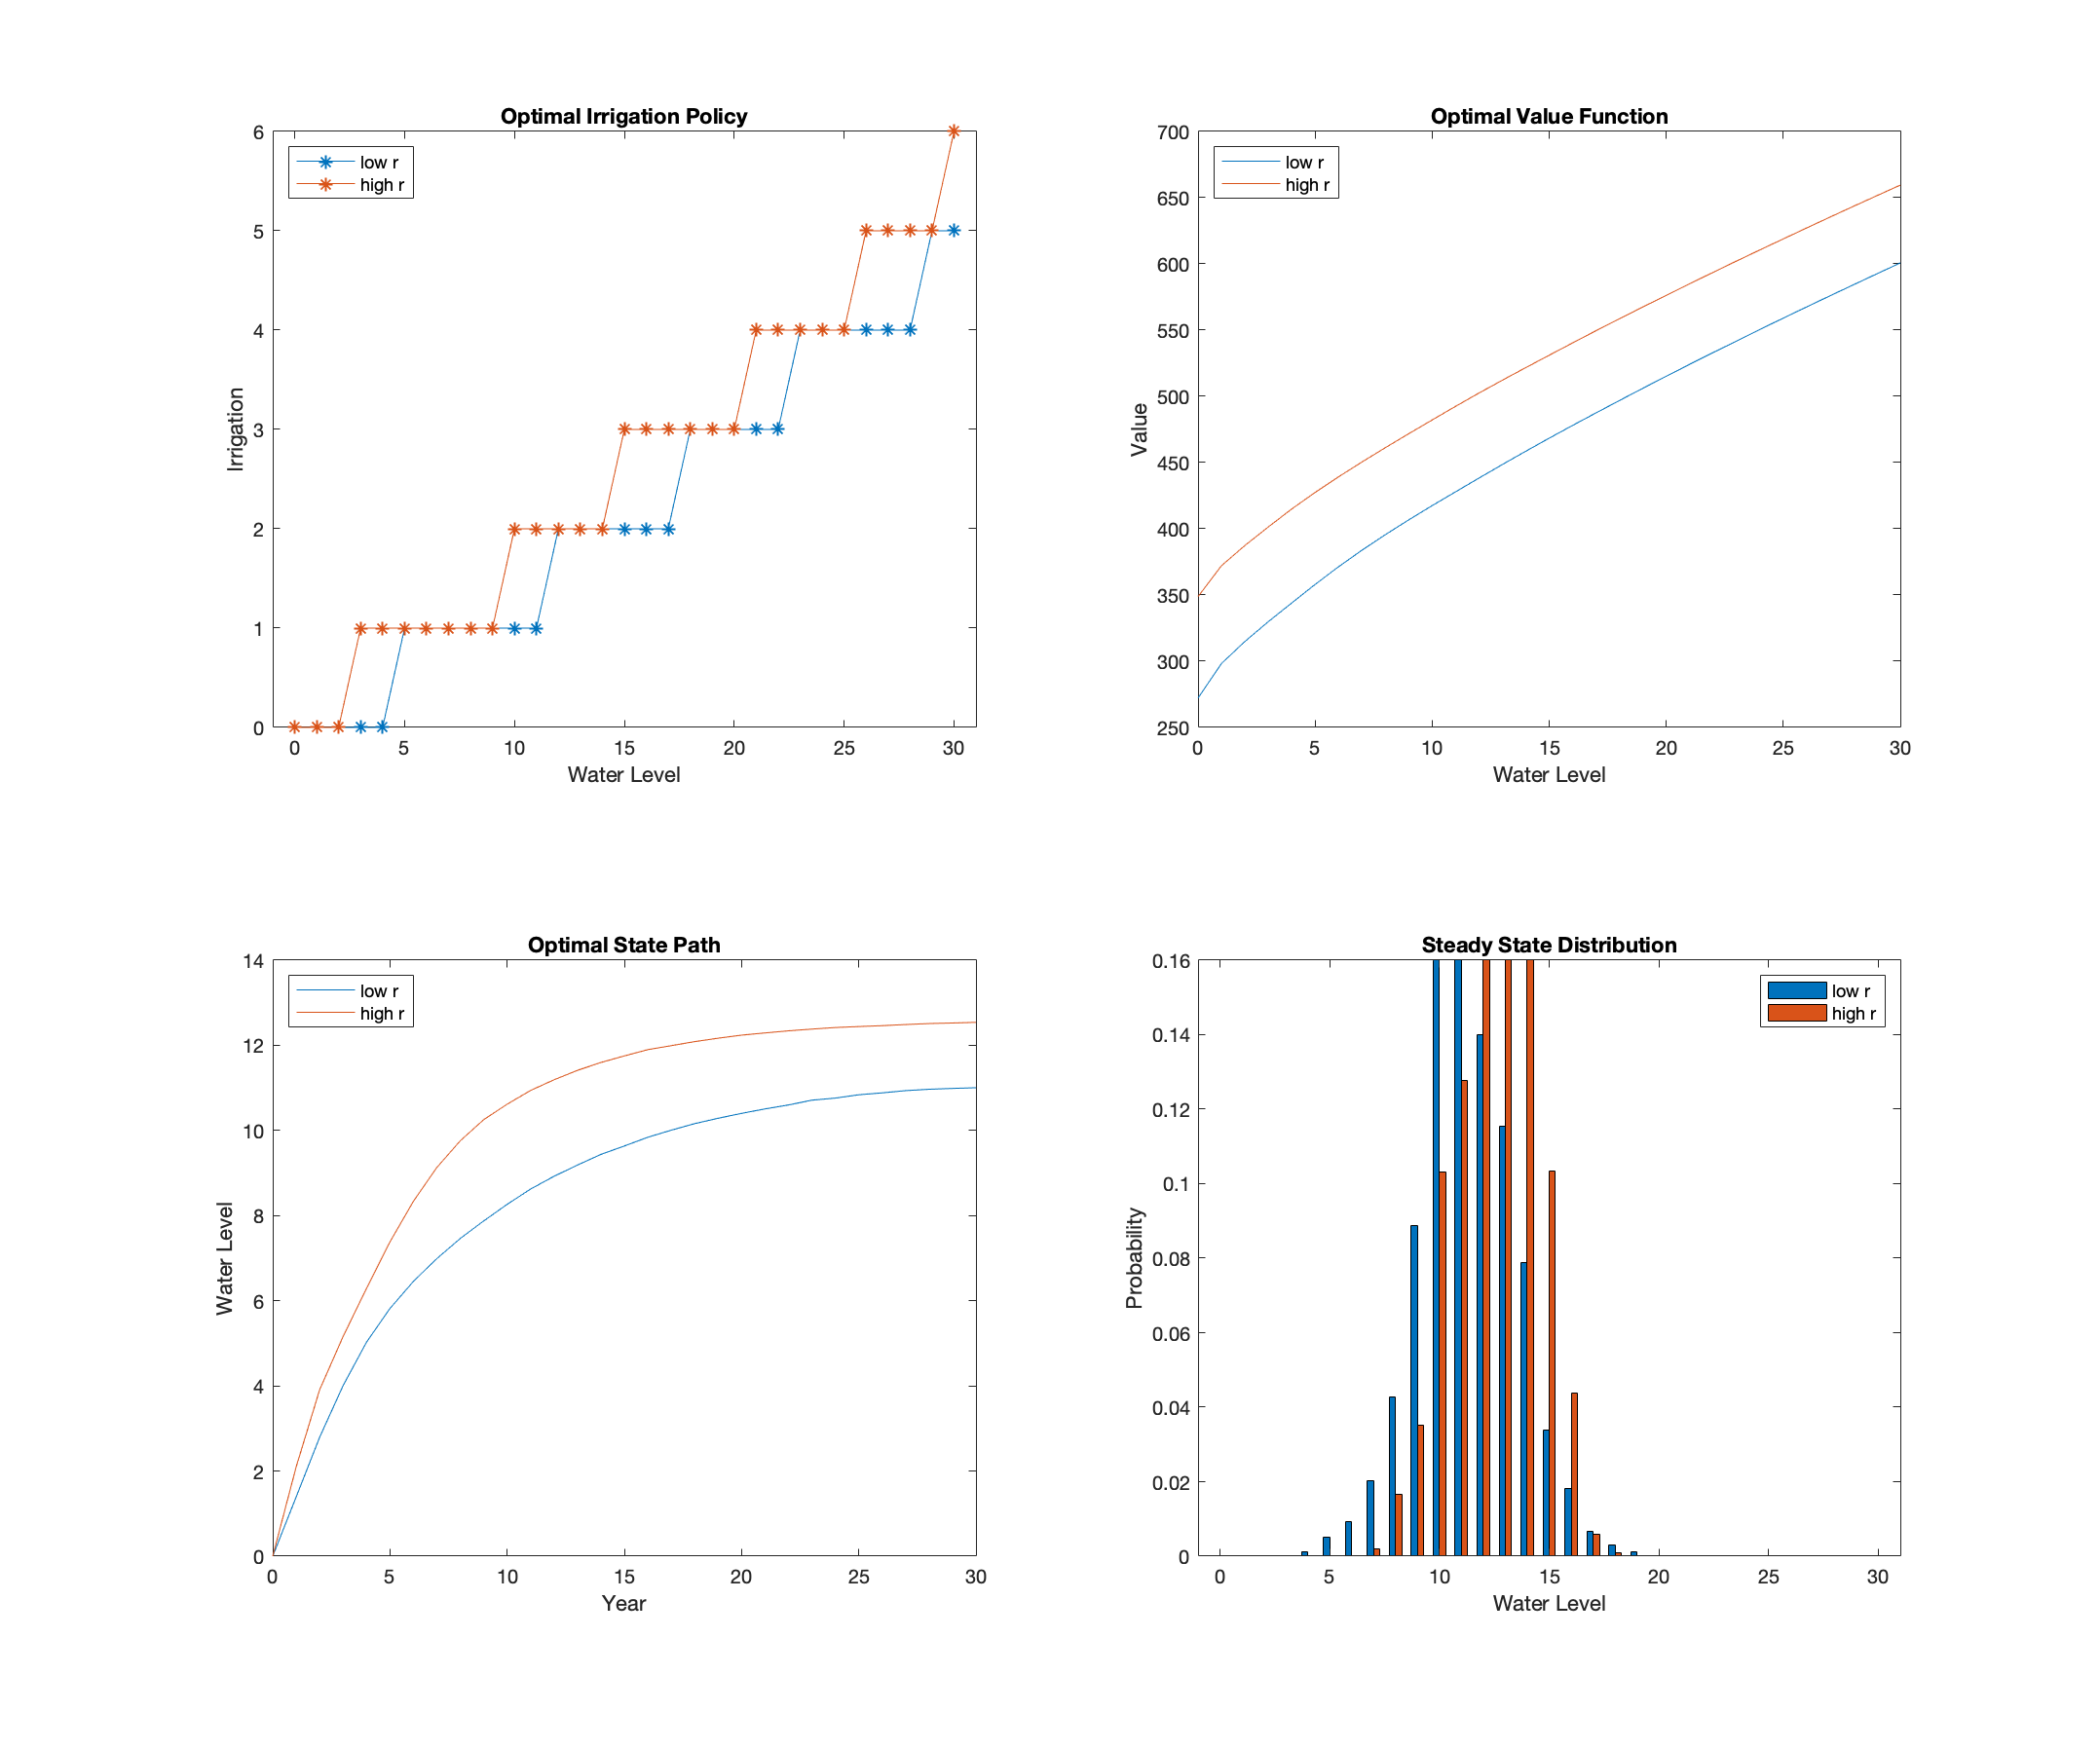

% Compute steady state distribution of water level
  subplot(2,2,4); 
  for l=1:size(p,1)
      pstar = pstarc(:,:,l);
      pi = markov(pstar);
      pic(:,l) = pi; 
  end
  
  h=bar(S,pic,1,'grouped'); %set(h,'FaceColor',[.75 .75 .75])
  title('Steady State Distribution');
  xlabel('Water Level'); ylabel('Probability'); 
  xlim([-1 31])
  ylim([0 0.16])
  legend({'low r', 'high r'});

% Compute steady-state water level
  avgstock = (pic'*S)

avgstock =    11.2468
   12.6044


  A = ["low";num2str(avgstock(1))];
  B = ["high";num2str(avgstock(2))];
  fprintf('\nSteady-state stock for %4s rainfall scenario is %8.2f\n',A,B)


Steady-state Stock for  low rainfall scenario is    11.25

Steady-state Stock for high rainfall scenario is    12.60


### In Lab Exercise:

Modify the above script to conduct a sensitivity analysis:

A climatologist predicts the rainfall pattern will change in the study region in the future and the predicted rainfall distribution in the next 50 years is given below.


$$r={0,1,2,3,4}$$



$$p(r)={0.2,0.5,0.1,0.1,0.1}$$


What is the impact of the climate change on the optimal irrigation policy, and steady state distribution of the water level in the reservoir?